addpath(genpath('src'));
addpath(genpath('model'));

# **1. INTRODUCTION**

Data preprocessing constitutes the backbone of data science.

After an initial phase of data mining, raw data—despite representing a potentially valuable source of information—often present multiple imperfections that hinder analysis and modeling. For this reason, working with such data is strongly discouraged and, in many cases, infeasible. These data can be incomplete, contain incorrect values, outliers, or duplicate information, be disorganized, or be stored in a non-standard or incompatible format for the chosen analysis tools.

The numerous existing preprocessing techniques, therefore, involve manipulating or selecting raw data. It is challenging to cover all these techniques in a single document, especially because most of them are not universally applicable but are instead highly dependent on the specific use case and the application domain.

These considerations underpin the decision to address the topic in relation to a specific theoretical regression use case, highlighting the benefits that various preprocessing techniques can provide when correctly applied to the chosen dataset.

The main objective is, therefore, to evaluate and apply various methods that enable an efficient analysis of data behavior, even through the simplest model: linear regression.

# **2. DATASET**

A careful selection of the dataset for this project is fundamental to obtaining valid and meaningful results. Every dataset has its own nature, a variety of intrinsic characteristics, and a specific ability to "respond" positively to preprocessing techniques. Therefore, it was necessary to choose and analyze a dataset that is well-suited for educational purposes.

The selected dataset is one of the multiple existing versions of the Housing Prices dataset. Specifically, a relatively complex variant was chosen: it consists of 81 variables (including the target variable SalePrice), which are numerical, categorical, and binary, with a relatively small number of rows. There are 2,919 observations, of which only half are usable for model training, while the remaining portion constitutes the unseen data.

## **2.1 Loading and Analysis the Data**

% Load the dataset as a table
dataset = readtable('data/HousePrices.csv','VariableNamingRule','preserve');

% Display the dataset
disp(dataset)

% Display characteristics of each variable in the dataset
summary(dataset)

# **3. DATA CLEANING**

To begin with, it is necessary to apply transformations to the dataset to make it interpretable, i.e., readable, by a learning model. A meticulous data-cleaning process must be executed to ensure, with a certain level of reliability, the correctness of the dataset.

## **3.1 Removing the Id Feature**

The observation identifier constitutes an actual feature of the dataset in this case. Keeping it would be highly detrimental, as it is completely unrelated to variations in the target SalePrice. Therefore, it must be removed from the dataset.

% Remove the 'Id' column
dataset = removevars(dataset, 1);

## **3.2 Converting the Categorical Features**

Many pieces of information are expressed qualitatively as string-type data. These categorical features must be converted into numerical attributes to be interpretable by a mathematical model.

For future applications, the function keeps track of categorical features even after their numerical conversion by creating and storing a binary row vector (0s and 1s).

% Handle categorical features
dataset = ConvertCategoricalFeatures(dataset);

## **3.3 Handling the Missing Values**

Missing data can pose a significant issue for a dataset. A high presence of NaN values can make it impossible to reconstruct the trend of a characteristic relative to the target, introducing substantial noise.

To address this, missing values are handled in three main steps:

- Column-level check: Features with more missing values than a set threshold are removed.

- Row-level check: Observations with a high concentration of missing values are removed.

- NaN replacement: Remaining missing values are replaced with the mean of the corresponding feature.

% Handle missing values
dataset = HandleMissingValues(dataset); % 5

## 3.4 **Encoding the Categorical Features**

Even when categorical features contain only numerical values, their presence in a dataset can influence model performance, particularly in preprocessing techniques such as normalization.

One-hot encoding is used to convert categorical columns into binary variables, improving the model’s ability to interpret relationships within the dataset.

% Perform one-hot encoding
dataset = OneHotEncoding(dataset);

## **3.5 Segmenting the Dataset**

Since missing values appear from a certain row onward in the SalePrice column, the dataset needs to be segmented into two parts:

- model_data, which contains no missing values and will be used for model training.

- unseen_data, which will be used later for a final test.

% Segment the dataset
[model_data, unseen_data] = SegmentDataset(dataset);

## **3.6 Shuffling the Data**

Shuffling the dataset is a crucial step to break any pre-existing ordering patterns that may negatively affect generalization.

% Shuffle the dataset with a fixed seed for reproducibility
rng(10);
new_order = randperm(size(model_data, 1));
model_data = model_data(new_order, :);

# **4. LINEAR REGRESSION**

After completing the data cleaning phase, it is crucial to highlight the importance of the preprocessing techniques that will be subsequently implemented by attempting to train a learning model on the obtained data.

Since this dataset is now interpretable and usable, it can be evaluated based on the results obtained from applying a learning model: a linear regression.

## **4.1 Splitting the Data**

Initially, the dataset is divided into three subsets: training, validation, and test sets.

% Split the dataset into training, validation, and test sets
[X_train, y_train, X_val, y_val, X_test, y_test] = SplitDataset(model_data);

## **4.2 Creating and Training the Model**

Creating a model without a concrete logic for choosing hyperparameters is possible, but fundamentally useless, especially in a complex and unprocessed context.

Arbitrarily assigning values for learning rate, epochs, and the regularization factor (lambda), the result is inevitably unsuccessful.

% Create the model (with arbitrarily selected parameters)
linearRegression = LinearRegressionClass(0.0001, 100, 0.01);
% Train the model
linearRegression = linearRegression.fit(X_train, y_train, X_val, y_val);
% Generate the cost evolution plot
linearRegression.plot_cost_history();

% Compute the R^2 score
r2 = linearRegression.computeScore(X_test, y_test);
fprintf('R^2 score: %.4f', r2);

% Compute RMSE error
linearRegression.computeError(X_test, y_test);

By analyzing the cost evolution plot and the error calculation, it becomes evident that due to the dataset's complexity and the lack of proper preprocessing and hyperparameter tuning, the model fails to understand the data behavior, diverging and generating an error that is impossible to evaluate (likely due to division by zero).

## 4.3 Performing the Grid Search

By using a hyperparameter tuning technique, such as Grid Search with cross-validation, it is possible to determine the best values among a finite pool of options by performing cross-validation on a limited number of parameter combinations within a relatively short processing time.

% Perform Grid Search
kCV = input('Set the number of folds for cross-validation: '); % 5
[lr, epochs, lmd] = GridSearch(model_data, kCV);

% Create the model (with Grid Search parameters)
linearRegression = LinearRegression(lr, epochs, lmd);
% Train the model
linearRegression = linearRegression.fit(X_train, y_train, X_val, y_val);

% Generate the cost evolution plot
linearRegression.plot_cost_history();
% Set x and y axis limits
xlim([0 100]);
ylim([3.5e+9 7e+9]);

% Compute R^2 score 
r2 = linearRegression.compute_r2_score(X_test, y_test);
fprintf('Indice r^2 : %.4f', r2);

% Compute RMSE error
linearRegression.compute_rmse(X_test, y_test);

The GridSearch function highlighted significant difficulties for the model in understanding and generalizing the data behavior. This issue is underscored by three results:

- A very low learning rate, which prevents the model from diverging but also hinders improvements, as it is too low to surpass the first local minimum or plateau it encounters.

- Maximum values for epochs and lambda, which may indicate particular instability in the model.

- A negative R^2 value, suggesting that the learning model is entirely unable to follow the dataset's behavioral trend, performing worse than a simple horizontal line.

# **5 DATA TRANSFORMATION **

At this stage, modifying the format in which data is expressed may be essential to simplify comparison, making the learning model more efficient. This macro-category includes techniques such as normalization and standardization.

## **5.1 Normalizing the Data**

Normalization is a process of rescaling data to fit within a common scale and adapt to a specific range (e.g., between 0 and 1) without altering their distribution. In the specific case of the examined dataset, data spans multiple orders of magnitude, which may result in certain features dominating over others of lower magnitude, requiring correction.

### **5.1.1 Applying the Min-Max Normalization without Outlier Handling**

The Min-Max normalization process is based on the following formula:

$\textrm{normalized}\;\textrm{value}=\frac{\textrm{original}\;\textrm{value}-\textrm{minimum}\;\textrm{value}}{\textrm{maximum}\;\textrm{value}-\textrm{minimum}\;\textrm{value}}*\left(b-a\right)+a$,

where the original value represents the feature value to be normalized, 'minimum value' and 'maximum value' represent the minimum and maximum values that the feature can assume, respectively, while 'a' and 'b' are the range margins chosen (in this case, 0 and 1).

% Perform Min-Max normalization
normalized_data = MinMaxNormalization(model_data, kCV); % 3

% Split dataset
[X_train, y_train, X_val, y_val, X_test, y_test] = SplitDataset(normalized_data);
% Perform Grid Search
[lr, epochs, lmd] = GridSearch(normalized_data, kCV);

% Create the model (with Grid Search parameters)
linear_regression = LinearRegression(lr, epochs, lmd);
% Train the model
linear_regression = linear_regression.fit(X_train, y_train, X_val, y_val);
% Generate the cost evolution plot
linear_regression.plot_cost_history();
% Set x and y axis limits
xlim([0 50]);
ylim([2e+9 8e+9]);

% Compute R^2 score
r2 = linear_regression.compute_r2_score(X_test, y_test);
fprintf('R^2 score: %.4f', r2);

% Compute RMSE error
linear_regression.compute_rmse(X_test, y_test);

It is important to note that, even with just normalizing the dataset, the learning model is already able to provide an approximation of the data behavior that is at least better than a simple horizontal line, achieving a finally positive R^2 index.

### **5.1.2 Applying the Min-Max Normalization with Outlier Handling**

Outliers—anomalous values that are significantly distant from most observations—can severely impact the performance of numerical transformations such as Min-Max normalization. For this reason, it makes sense to manage them by either eliminating or replacing problematic values.

Regarding the analyzed dataset, the effects of both approaches were examined, but only after a common initial step: removing the most problematic columns, specifically those containing a number of outliers exceeding a predefined threshold.

Once these columns—considered problematic due to their excessive instability—were removed, two different strategies were tested. First, the effect of eliminating examples containing a number of anomalies above a preset limit was evaluated. Then, the effect of replacing those anomalies with the mean value computed for the corresponding column was also examined.

In relatively linear contexts, an elimination-based approach can provide greater benefits than substitution, which is more suitable for cases where losing information could severely compromise model performance. In both cases, it is advisable to set a certain tolerance threshold to account for the possible presence of significant anomalies rather than simple detection errors or similar issues.

- `C`**ase with Elimination:**

% Perform outlier handling (1: display plots, 0: do not display plots)
outlier_data = HandleOutliers(model_data, 'elimination', 1); % 3,3,3,3

% Perform Min-Max normalization
normalized_data = MinMaxNormalization(outlier_data, kCV);

% Perform Grid Search
[~, ~, ~] = GridSearch(normalized_data, kCV);

- **Case with Substitution:**

% Perform outlier handling (1: display plots, 0: do not display plots)
outlier_data = HandleOutliers(model_data, 'substitution', 1); % 3,3,2,3

% Perform Min-Max normalization
normalized_data = MinMaxNormalization(outlier_data, kCV);

% Perform Grid Search
[~, ~, ~] = GridSearch(normalized_data, kCV);

It can be stated that, in this context, outliers do not significantly impact the dataset, which is why their management leads to only a limited improvement in performance. Furthermore, it is more advantageous to correct examples containing multiple outliers by replacing them with the mean rather than eliminating them.

However, this is not an *absolute* result. By modifying and testing different values for the considered parameters (e.g., the minimum number of unique elements required for normalization, step size, minimum number of outliers, etc.), different observations may be obtained, potentially leading to better results than the current ones.

## **5.2 Standardizing the Data**

Standardization is a process that transforms a data distribution into a new distribution with zero mean and unit standard deviation, making the data comparable and of similar scale.

This process is performed by subtracting the mean of the data distribution and dividing by the standard deviation. The formula for standardization is as follows:

$z=\frac{\left(x-\mu \right)}{\sigma }$,

where *x* is the observed value, *μ* is the mean of the distribution, and *σ* is the standard deviation of the distribution.

In general, normalization is preferable when the distribution is unknown or asymmetric and when it is necessary to scale the data within a specific range. Standardization, on the other hand, is preferred if the data follows a normal distribution or when comparing the relative importance of different features.

FeatureDistribution(model_data);

Considering that binary features and those with a limited number of unique values are not included in the standardization function, analyzing the distribution of a sample of dataset features reveals that many of the features involved in this process follow a normal distribution. Only a small number exhibit a uniform behavior or one close to a Dirac delta distribution.

This suggests that applying Z-Score standardization is likely to yield highly positive results. However, it would be meaningless—or even counterproductive—to apply it alongside normalization, as these two techniques generally aim for different objectives.

### **5.2.1 Applying the Z-Score Standardization**

The performance results obtained through Z-Score standardization are analyzed:

% Perform outlier handling (1: display plots, 0: do not display plots)
outlier_data = HandleOutliers(model_data, 'substitution', 0); % 3,3,2,4

% Perform Z-Score standardization
standardized_data = ZScoreStandardization(outlier_data, kCV);

% Split the dataset
[X_train, y_train, X_val, y_val, X_test, y_test] = SplitDataset(standardized_data);

% Perform Grid Search
[lr, epochs, lmd] = GridSearch(standardized_data, kCV);

% Create the model (with Grid Search parameters)
linear_regression = LinearRegression(lr, epochs, lmd);
% Train the model
linear_regression = linear_regression.fit(X_train, y_train, X_val, y_val);

% Generate the cost evolution plot
linear_regression.plot_cost_history();
% Set x and y axis limits
xlim([0 epochs]);
ylim([5e+8 14e+9]);

% Compute R^2 score
r2 = linear_regression.compute_r2_score(X_test, y_test);
fprintf('R^2 score: %.4f', r2);

% Compute RMSE error
linear_regression.compute_rmse(X_test, y_test);

The highly positive result clearly demonstrates how efficient Z-Score standardization is in this specific case study, achieving a score significantly higher than what was obtained using Min-Max normalization.

# **6 DIMENSIONALITY REDUCTION**

Dimensionality reduction is a preprocessing concept that encompasses various techniques aimed at reducing dataset complexity, facilitating analysis, and mitigating the effect of the curse of dimensionality (the exponential deterioration in the performance of a linear learning model as the number of dimensions increases when representing a non-linear dataset).

In this case, since the chosen learning model is a simple linear regression, applying dimensionality reduction can significantly improve its performance without compromising its ability to represent and generalize the data behavior.

In general, before applying these techniques, it is advisable to perform normalization to ensure a more consistent comparison of the mathematical parameters of the features.

The techniques involved—among the most important in this domain—are feature selection and Principal Component Analysis (PCA).

## **6.1 Selecting the Features**

Feature selection involves manually selecting a limited number of features deemed most significant for the analyzed problem. A common selection criterion is the correlation between dataset features and the target feature: a strong correlation, whether positive or negative, can significantly influence the behavior of the learning model, whereas a weak correlation can introduce noise, thereby acting as a disturbance.

This approach is undoubtedly very simple and intuitive, but at the same time, it can lead to severe information loss since the discarded features are entirely removed from the dataset.

### **6.1.1 Selecting the Features using the Min-Max Normalization**

First, before proceeding with feature selection, it is necessary to apply some fundamental preprocessing techniques to facilitate a mathematical comparison between the various features of the dataset.

Specifically, outlier values are replaced, and Min-Max normalization is applied.

% Perform outlier handling (1: display plots, 0: do not display plots)
outlier_data = HandleOutliers(model_data, 'substitution', 0); % 3,3,2,3

% Perform Min-Max normalization
normalized_data = MinMaxNormalization(outlier_data, kCV);

At this point, a correlation-based feature selection can be performed. A first manual approach is considered, which inevitably results in lower performance compared to the next method. The second approach is more automated and integrates model evaluation using a modified version of Grid Search that also explores different correlation threshold values.

-  `Manual analysis:`

% Perform feature selection
selected_data = SelectFeatures(normalized_data, kCV); % 0.3

By analyzing the histogram, an appropriate correlation threshold can be estimated to ensure the retention of a reasonable number of features. This prevents including too many features, which could introduce noise, or too few, which could lead to excessive information loss.

Once the threshold is determined, a Grid Search analysis is performed.

% Split the dataset
[X_train, y_train, X_val, y_val, X_test, y_test] = SplitDataset(selected_data);

% Perform Grid Search
[lr, epochs, lmd] = GridSearch(selected_data, kCV);

% Create the model (with Grid Search parameters)
linear_regression = LinearRegression(lr, epochs, lmd);
% Train the model
linear_regression = linear_regression.fit(X_train, y_train, X_val, y_val);

% Generate the cost evolution plot
linear_regression.plot_cost_history();
% Set x and y axis limits
xlim([0 epochs]);
ylim([1e+9 8e+9]);

% Compute R^2 score
r2 = linear_regression.computeScore(X_test, y_test);
fprintf('R^2 score: %.4f', r2);

% Compute RMSE error
linear_regression.computeError(X_test, y_test);

By comparing this score with the one obtained using only Min-Max normalization with outlier handling (~0.16), it can be concluded that, even with a rough estimation, model performance can be further and significantly improved.

- `Automated analysis:`

To achieve the best possible result, or at least something close to it, modifications are made to the Grid Search and feature selection functions. These modifications allow for analyzing a large number of combinations by including different correlation thresholds in the grid search.

% Perform global Grid Search
[lr, epochs, lmd, correlation] = CorrelationGridSearch(normalized_data, kCV);

% Reconstruct the best model result:
% Perform feature selection using the optimal correlation threshold
selected_data = AutoSelectFeatures(normalized_data, correlation, kCV);

% Split the dataset
[X_train, y_train, X_val, y_val, X_test, y_test] = SplitDataset(selected_data);

% Create the model (with Grid Search parameters)
linear_regression = LinearRegression(lr, epochs, lmd);
% Train the model
linear_regression = linear_regression.fit(X_train, y_train, X_val, y_val);

% Generate the cost evolution plot
linear_regression.plot_cost_history();
% Set x and y axis limits
xlim([0 epochs]);
ylim([1e+9 5e+9]);

% Compute R^2 score
r2 = linear_regression.computeScore(X_test, y_test);
fprintf('R^2 score: %.4f', r2);

% Compute RMSE error
linear_regression.computeError(X_test, y_test);

The improvement in performance, as indicated by the R² index, is limited. However, as previously stated in relation to outlier handling, investing more time and resources in this initial analysis phase can still be worthwhile.

### **6.1.2 Selecting the Features using the Z-Score Standardization**

Feature selection can also be applied to a dataset standardized using Z-Score.

The following procedure was performed, but it did not result in improved performance, likely due to excessive simplification of the dataset, which led to overfitting.

% Perform outlier handling (1: display plots, 0: do not display plots)
outlier_data = HandleOutliers(model_data, 'substitution', 0); % 3,3,2,4

% Perform Z-Score standardization
standardized_data = ZScoreStandardization(outlier_data, kCV);

% Perform Grid Search with correlation
[~, ~, ~, ~] = CorrelationGridSearch(standardized_data, kCV);

## **6.2 Performing the PCA**

Principal Component Analysis (PCA), as previously mentioned, is a multivariate analysis technique used to identify underlying patterns in data and reduce the dimensionality of a dataset while preserving as much information as possible.

This technique aims to identify the most impactful information within the dataset. These key pieces of information are combined linearly to create a new space composed of new variables, known as principal components.

Principal components are computed in such a way that they capture the maximum variation in the data. They represent the directions in which the data varies the most, with the first principal component accounting for the highest possible variance.

### **6.2.1 Performing the PCA using the Z-Score Standardization**

Before applying PCA, it is advisable to perform a data transformation. In this case, standardization has been carried out, resulting in a standard normal distribution—i.e., zero mean and unit variance.

To implement PCA from scratch, the following steps must be followed:

- Compute the covariance matrix of the dataset’s features.

- Perform Singular Value Decomposition (SVD) on the covariance matrix using the svd function. In MATLAB, this function returns eigenvectors directly ordered in descending order based on their corresponding eigenvalues.

- Select k, the number of principal components to retain.

- Construct the projection matrix for the selected k principal components.

- Create the new k-dimensional space for the dataset.

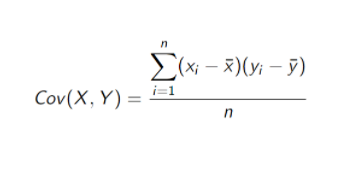                            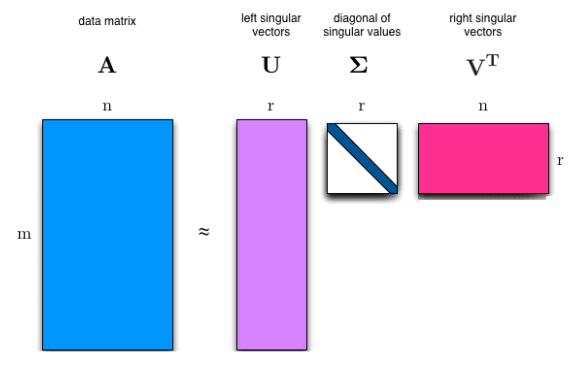

Using Singular Value Decomposition (SVD), the standardized dataset matrix X is factorized into the form USV’, where U represents the matrix of orthonormal eigenvectors of the columns of X, S is the diagonal matrix containing the eigenvalues, and V is the matrix of orthonormal eigenvectors of the rows of X.

The diagonal matrix S is used to determine how many principal components should be retained to achieve a desired percentage of represented information (explained variance). The U matrix of eigenvectors is then used to reconstruct the dataset with reduced dimensionality.

- `Manual analysis:`

A manual approach was initially chosen for this case as well, where the number of principal components to retain is determined based on the visual analysis of the explained variance plot. This is then followed by an automated approach using a modified Grid Search specifically designed for this scenario.

% Perform outlier handling (1: display plots, 0: do not display plots)
outlier_data = HandleOutliers(model_data, 'substitution', 0); % 3,3,3,4,2

% Perform Z-Score standardization
standardized_data = ZScoreStandardization(outlier_data, kCV);

% Split train-test data
split = (kCV-1)/kCV;
Index = ceil(size(standardized_data, 1) * split);
train_data = standardized_data(1:Index, :);
test_data = standardized_data(Index:end, :);

% Handle overlap
test_data(1, :) = [];

% Evaluate training data:
% Compute the number of observations
samples = size(train_data, 1);

% Isolate the target feature
X = train_data(:, 1:end-1);
Y = train_data(:, end);

X_test = test_data(:, 1:end-1);
Y_test = test_data(:, end);

% Compute the covariance matrix
covariance_matrix = (X' * X) / (samples - 1);

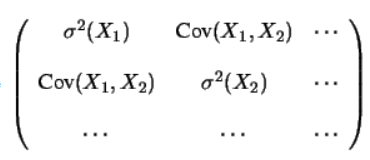

% Perform Singular Value Decomposition (SVD)
[U, S, ~] = svd(covariance_matrix);

% Compute eigenvalues
eigenvalues = diag(S);

% Compute the explained variance percentages for the first k principal components
total_variance = sum(eigenvalues);
explained_variance = cumsum(eigenvalues) / total_variance;

% Display a plot showing how the percentage of represented data changes
% as the number of selected principal components increases.
figure;
plot(1:length(eigenvalues), explained_variance, 'ro-', 'LineWidth', 2, 'MarkerFaceColor', 'w');
xlabel('Principal Components');
ylabel('Explained Variance Percentage');
title('Scree Plot');

k = input('Enter the number of principal components to retain: '); % 2

% Transform the data using the selected principal components
X_pca_train = X * U(:, 1:k);
X_pca_test = X_test * U(:, 1:k);
pca_train_data = [X_pca_train Y];
pca_test_data = [X_pca_test Y_test];

% Reconstruct the dataset
pca_data = [pca_train_data; pca_test_data];

% Split the dataset
[X_train, y_train, X_val, y_val, X_test, y_test] = SplitDataset(pca_data);

% Perform Grid Search
[lr, epochs, lmd] = GridSearch(pca_data, kCV);

% Create the model (with parameters from Grid Search)
linear_regression = LinearRegression(lr, epochs, lmd);
% Train the model
linear_regression = linear_regression.fit(X_train, y_train, X_val, y_val);
% Generate the cost evolution plot
linear_regression.plot_cost_history();
% Set x and y axis limits
xlim([0 epochs]);
ylim([6e+8 5e+9]);

% Compute R^2 score
r2 = linear_regression.compute_r2_score(X_test, y_test);
fprintf('R^2 score: %.4f', r2);

% Compute RMSE error
linear_regression.compute_rmse(X_test, y_test);

The use of PCA as a dimensionality reduction technique, in this specific application, demonstrates a significant improvement in the model’s performance and its ability to generalize the dataset.

- `Automated analysis:`

As previously done, performance can be further improved by automating a restricted analysis over a finite number of combinations that consider different selections of the parameter *k*.

[lr, epochs, lmd, k] = PCAGridSearch(standardized_data, kCV);